# Sensing System - Performance Evaluation

## Initialize the Evaluation Script

clear;
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
 file_path = "4GHz.json";

config_path = david_path + file_path;

### Generate a test set parameters for evaluating performance

%specify maximum constraints
valid_slopes = [1,100];
valid_chirp_periods = [15,100];
valid_BWs_MHz = [30,3500];
num_adc_samples = 128;
num_cases = 200;

simulator = Simulator_revB();
            
simulator.load_params_from_JSON(config_path);

[slopes,chirp_periods,adc_sampling_rates] = ...
    characterization_functions.initialize_sensing_subsystem_test_cases_general(num_cases, ...
                valid_slopes, ...
                valid_chirp_periods, ...
                valid_BWs_MHz, ...
                num_adc_samples);

configurations_passed = characterization_functions.check_test_configurations(slopes, ...
    chirp_periods, ...
    adc_sampling_rates, ...
    num_adc_samples, ...
    config_path);

All Configurations passed 


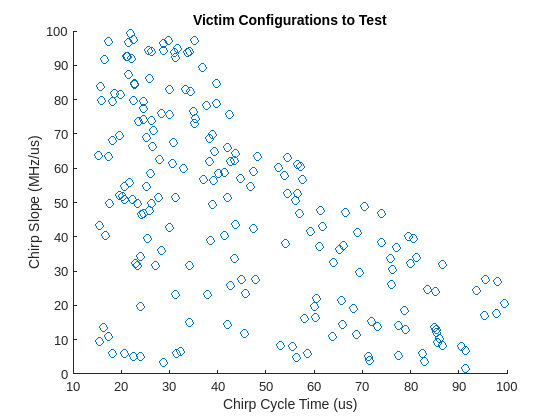

characterization_functions.plot_test_configurations(slopes,chirp_periods);

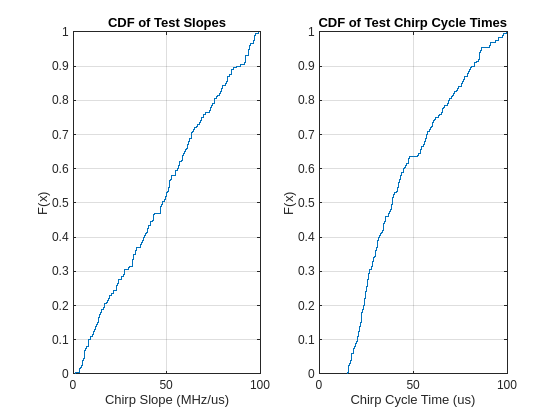

characterization_functions.plot_test_configuration_cdfs(slopes,chirp_periods);

### Run all of the test configurations and save results to a file

%running troublesome configurations
slopes = slopes(2:end,:);
chirp_periods = chirp_periods(2:end,:);
adc_sampling_rates = adc_sampling_rates(2:end,:);

frames_to_compute = 7;

testing_data = characterization_functions.run_sensing_performance_test_cases( ...
                num_cases, ...
                frames_to_compute, ...
                slopes, ...
                chirp_periods, ...
                adc_sampling_rates, ...
                num_adc_samples, ...
                config_path, ...
                "sensing_subsystem_test_data.csv"); 

### Plot testing results

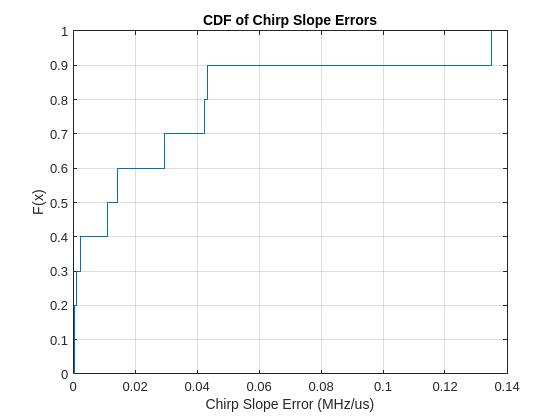

summary_table = 1×4 table
    Mean (MHz/us)    Variance (MHz/us)^2    MSE (MHz/us)^2    95th Percentile (MHz/us)
    _____________    ___________________    ______________    ________________________

      0.027977            0.0016918           0.0023053               0.13486         


%plot the cdf of the chirp slope errors
read_file_path = "sensing_subsystem_test_data.csv";
summary_table = characterization_functions.generate_slope_estimation_summary(read_file_path)

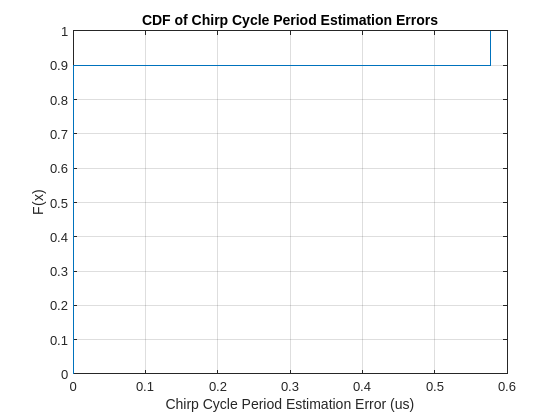

summary_table = 1×4 table
    Mean (us)    Variance (us)^2    MSE (us)^2    95th Percentile (us)
    _________    _______________    __________    ____________________

    0.057764         0.03329         0.033297           0.57704       


summary_table = characterization_functions.generate_chirp_period_estimation_summary(read_file_path)

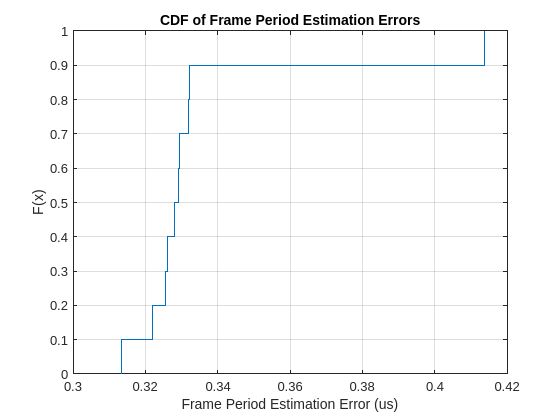

summary_table = 1×4 table
    Mean (us)    Variance (us)^2    MSE (us)^2    95th Percentile (us)
    _________    _______________    __________    ____________________

     0.33518       0.00079354        0.11306            0.41383       


%summary_table = characterization_functions.generate_frame_period_estimation_summary(read_file_path)

### Test Chirp Slopes

%initialize variables for different scenarios
chirp_cycle_period_us = 50;
% slopes_to_compute = 0.5:0.05:1.4; %for 20 MHz
% slopes_to_compute = 2.5:0.25:5; %for 100 MHz
% slopes_to_compute = 22:2:50; %for 1 GHz
slopes_to_compute = 100:10:200; %for 4 GHz
%for low slopes, need to go into
%Radar_Signal_processor/configure_low_pass_filter, and change to low
%stopband
frames_to_compute = 5;

%initialize variables to store results
num_test_cases = size(slopes_to_compute,2);
actual_slopes = zeros(1,num_test_cases);
estimated_slopes = zeros(1,num_test_cases);

%variable to store the error
errors = zeros(1,num_test_cases);

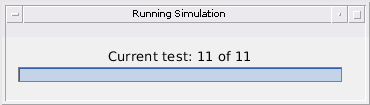

i = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
progress_bar = waitbar(0,status,"Name","Running Simulation");
for i = 1:num_test_cases

    status = sprintf("Current test: %d of %d",i, num_test_cases);
                        waitbar(i/num_test_cases,progress_bar,status);
    [actual_slope,estimated_slope,...
        actual_chirp_duration,estimated_chirp_duration,...
        actual_frame_duration, estimated_frame_duration] = ...
        compute_sensed_values(config_path,slopes_to_compute(i),chirp_cycle_period_us, frames_to_compute);
    %save values
    actual_slopes(i) = actual_slope;
    estimated_slopes(i) = estimated_slope;
    errors(i) = actual_slope - estimated_slope;
end

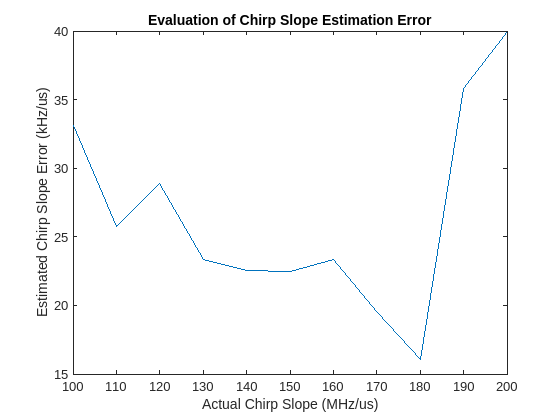

clf;
%convert error to kHz/us
errors_khz_us = errors * 1e3;
plot(actual_slopes,errors_khz_us)
title("Evaluation of Chirp Slope Estimation Error")
xlabel("Actual Chirp Slope (MHz/us)")
ylabel("Estimated Chirp Slope Error (kHz/us)")

%ylim([-10,10])
mean_error = mean(errors_khz_us);
var_error = var(errors_khz_us);

fprintf("Mean Error: %f kHz/us",mean_error);

Mean Error: 26.435573 kHz/us

fprintf("Range Error Varriance: %f kHz/us",var_error);

Range Error Varriance: 52.764857 kHz/us

### Test Chirp Period

%initialize variables for different scenarios

%20 MHz
%  chirp_cycle_periods_us = 25:1:50;
%  slope_MHz_us = 1.33;
%100 MHz
%  chirp_cycle_periods_us = 25:1:50;
%  slope_MHz_us = 5;
%1 GHz
%     chirp_cycle_periods_us = 25:1:50;
%     slope_MHz_us = 50;
%4 GHz
    chirp_cycle_periods_us = 25:1:50;
    slope_MHz_us = 200;


frames_to_compute = 5;

%initialize variables to store results
num_test_cases = size(chirp_cycle_periods_us,2);
actual_chirp_cycle_periods = zeros(1,num_test_cases);
estimated_chirp_cycle_periods = zeros(1,num_test_cases);

%variable to store the error
errors = zeros(1,num_test_cases);

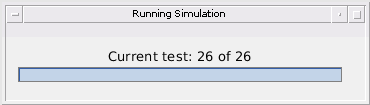

i = 1;
status = sprintf("Current test: %d of %d",1, num_test_cases);
                progress_bar = waitbar(0,status,"Name","Running Simulation");
for i = 1:num_test_cases

    status = sprintf("Current test: %d of %d",i, num_test_cases);
                        waitbar(i/num_test_cases,progress_bar,status);
    [actual_slope,estimated_slope,...
        actual_chirp_duration,estimated_chirp_duration,...
        actual_frame_duration, estimated_frame_duration] = ...
        compute_sensed_values(config_path,slope_MHz_us,chirp_cycle_periods_us(i), frames_to_compute);
    %save values
    actual_chirp_cycle_periods(i) = actual_chirp_duration;
    estimated_chirp_cycle_periods(i) = estimated_chirp_duration;
    errors(i) = actual_chirp_duration - estimated_chirp_duration;
end

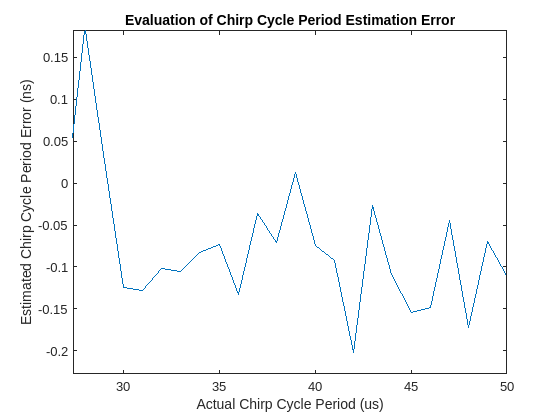

errors_ns = errors * 1e3;
clf;
plot(actual_chirp_cycle_periods,errors_ns)
title("Evaluation of Chirp Cycle Period Estimation Error")
xlabel("Actual Chirp Cycle Period (us)")
ylabel("Estimated Chirp Cycle Period Error (ns)")

%ylim([-1,1])
mean_error = mean(errors_ns);
var_error = var(errors_ns);

fprintf("Mean Error: %f ns",mean_error);

Mean Error: -0.075758 ns

fprintf("Range Error Varriance: %f ns",var_error);

Range Error Varriance: 0.005827 ns